%-------------------------introduction------------------------------

% This file is a demonstration code for the display effect of a dual splicing screen, 
% and the following lists the functions of the used libraries:

% MultipleTwoScreen : Generate a double-screen grid based on screen dimensions and resolution parameters, 
% initialize screen color, screen angle, and key points of screen rotation.

% Constructing_structure : Used to construct the background, the background used here is a six-sided sky box 
% (one side of the screen is replaced, becoming five sides), composed of five images.

% Exit_effect : Used in conjunction with Function Constructing_structure to create black frames on both sides of the background, 
% but the main point cloud is not restricted, creating an 'out-of-frame' effect.

% Cross : Find the key points on the extension line from the viewpoint to the key points on the screen to the
% slice.

% Condition_Two : Used to find the points that fall on the k th layer of the slice.

% which_pixel_Two : Map the specific coordinates of the point cloud onto the screen to convert them into coordinates in the pixel array.

% Coloring : The color displayed by the screen pixels can be set to the same color, but in most cases, 
% the point cloud itself needs to have color, and the color of each point is assigned to the corresponding pixels.

%-------------------------introduction------------------------------


clear;clc;
close all;
data = load('./config/two_screens_display.mat');

% Set screen parameters.
theta0 = 60;theta1 = 90;theta2 = 120;

eye = [150,-350,50];
l1 = data.params.l1;
l2 = data.params.l2;
h = data.params.h;
pixel_wide = data.params.pixel_wide;
pixel_high = data.params.pixel_high;

addpath(genpath('./src/background/'));
addpath(genpath('./src/Base/'));
[screens,colors,Key_points,xyz123] = MultipleTwoScreen(l1,l2,h,theta0,theta1,pixel_wide,pixel_high);

x_total = screens{1};
y_total = screens{2};
z_total = screens{3};

% Load the main point cloud and adjust its position.
ptCloud = pcread('F:\bunny\bunny\reconstruction\bun_zipper.ply');
M = 800*ptCloud.Location;
M(:, [2, 3]) = M(:, [3, 2]);
M(:,2) = -M(:,2) + 500;
M(:,1) = M(:,1) + 80;
M(:,3) = M(:,3) - 30;
points3D = M;

[corner1,corner2,corner3,corner4,edge1,edge2] = deal(Key_points{:});

screen = zeros(0, 3);
color_screen = zeros(0, 3);
points_time = [];
deep = 300;

% Load background images.
way_1 = "./imgs/background/background_1.png";
way_2 = "./imgs/background/background_2.png";
way_3 = "./imgs/background/background_3.png";
way_4 = "./imgs/background/background_4.png";
way_5 = "./imgs/background/background_5.png";

Color_matrix_origin = Constructing_structure(eye,x_total,y_total,z_total,deep,way_1,way_2,way_3,way_4,way_5);
Color_matrix = Exit_effect(screens,Color_matrix_origin, 0.2);

% Set the number of layers and load them layer by layer.
numFrames = 100;
for i = 1:numFrames
condition_all = false(0,1);
k = i/100.0;

layer_cross_point_1 = Cross_through_screens(eye,corner1,k);
layer_cross_point_2 = Cross_through_screens(eye,corner2,k);
layer_cross_point_3 = Cross_through_screens(eye,corner3,k);
layer_cross_point_4 = Cross_through_screens(eye,corner4,k);
layer_cross_point_5 = Cross_through_screens(eye,edge1,k);
layer_cross_point_6 = Cross_through_screens(eye,edge2,k);
layer_cross_Key_points = {layer_cross_point_1,layer_cross_point_2,layer_cross_point_3,layer_cross_point_4,layer_cross_point_5,layer_cross_point_6};

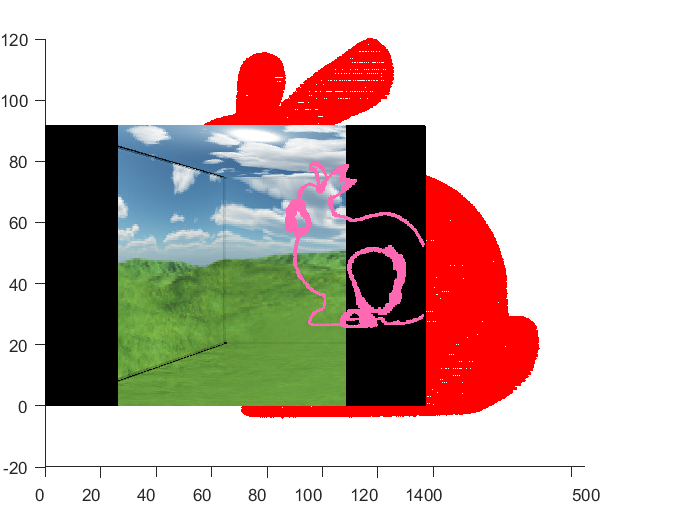

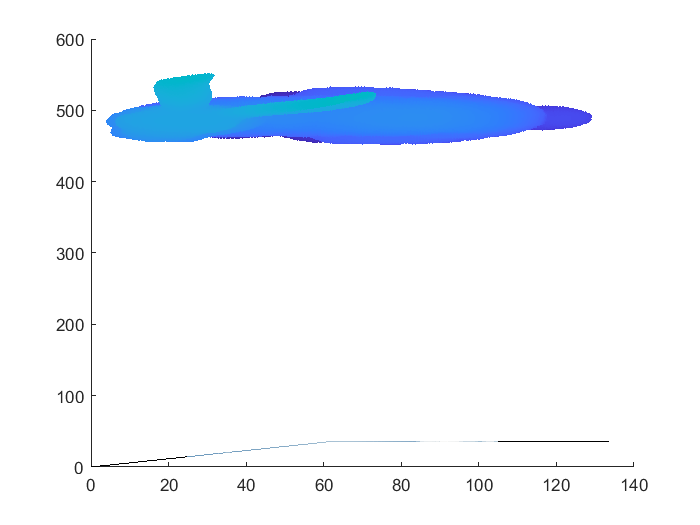

% Find the coordinates on the screen that correspond to the points on the slice, and perform the coloring work.
point_to_layer_condition = Condition_Two(points3D,layer_cross_Key_points,theta0,theta1);

[row_idx,~] = find(point_to_layer_condition == 1);

for m = 1:length(row_idx)

M0 = points3D(row_idx(m),:);

Pixel = (M0 + k*eye)/(1+k);
pixel_idx = which_pixel_Two(Pixel(1),Pixel(2),Pixel(3),pixel_wide,xyz123,theta0,theta1);

colorRGB = [255,105,180];
radius = 5;
Color_matrix = Coloring(Color_matrix, pixel_idx, colorRGB, radius, 'Round');
end

end

% Display the loading results, including the relative position of the screen and the point cloud.
figure;
hold on;
scatter3(points3D(:,1),points3D(:,2),points3D(:,3), ...
    5,"red",'filled');
h1 = surf(x_total, y_total, z_total,'FaceAlpha', 0.8, 'CData',Color_matrix, 'FaceColor', 'texturemap');% 绘制表面，并获取句柄
shading interp;
hold off;

ax = gca;

ax.CameraPosition = eye;  

ax.CameraTarget = [110,50,50];  

ax.CameraUpVector = [0, 0, 1]; 